% 11 jan 2017

% EXERCISE 1

syms q1 real
syms q2 real
syms q3 real
syms q4 real
syms N real

alpha = [0 -pi/2 0 0];
a=[0,N,0,0];
d=[q1 0 q3 0];
theta=[0,q2,0,q4];

table=[alpha',a',d',theta']

$$table = \left(\begin{array}{cccc} 0 & 0 & q_{1} & 0\\ -\frac{\pi }{2} & N & 0 & q_{2}\\ 0 & 0 & q_{3} & 0\\ 0 & 0 & 0 & q_{4} \end{array}\right)$$

%plot the robot
%Note: it has different format respect to Sveva's DHMatrix function
%l_a = 0.1
%l_d = 0.3

a_no_sym = double(subs(a, {N}, {0.1}));
alpha_no_sym = alpha;
d_no_sym = double(subs(d, {q1,q3}, {0,0}));
theta_no_sym = double(subs(theta, {q2,q4}, {0,0}));

DHTable=[a_no_sym', alpha_no_sym',d_no_sym',theta_no_sym']

DHTable =          0         0         0         0
    0.1000   -1.5708         0         0
         0         0         0         0
         0         0         0         0


joints = 'PRPR';
robot_model = build_robot_model(joints, DHTable);


config = homeConfiguration(robot_model)%build_configuration(robot_model, array_joint_values);

config = 1×4 struct array with fields:
    JointName
    JointPosition


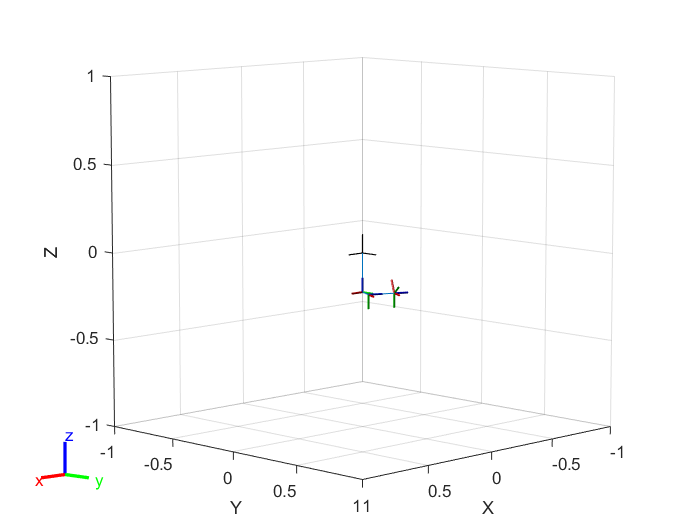


show(robot_model, randomConfiguration(robot_model));%config);

q_0 = [0 1 0 1]
config_q_0 = build_configuration(robot_model, q_0);
show(robot_model, config_q_0);

%B'
[T, A] = DHMatrix(table);
A0_1=A{1}

$$A0\_1 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & q_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A1_2=A{2}

$$A1\_2 = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & 0 & -\sin\left(q_{2}\right) & N\,\cos\left(q_{2}\right)\\ \sin\left(q_{2}\right) & 0 & \cos\left(q_{2}\right) & N\,\sin\left(q_{2}\right)\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A2_3=A{3}

$$A2\_3 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & q_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A3_4=A{4}

$$A3\_4 = \left(\begin{array}{cccc} \cos\left(q_{4}\right) & -\sin\left(q_{4}\right) & 0 & 0\\ \sin\left(q_{4}\right) & \cos\left(q_{4}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T

$$T = \left(\begin{array}{cccc} \cos\left(q_{2}\right)\,\cos\left(q_{4}\right) & -\cos\left(q_{2}\right)\,\sin\left(q_{4}\right) & -\sin\left(q_{2}\right) & N\,\cos\left(q_{2}\right)-q_{3}\,\sin\left(q_{2}\right)\\ \cos\left(q_{4}\right)\,\sin\left(q_{2}\right) & -\sin\left(q_{2}\right)\,\sin\left(q_{4}\right) & \cos\left(q_{2}\right) & N\,\sin\left(q_{2}\right)+q_{3}\,\cos\left(q_{2}\right)\\ -\sin\left(q_{4}\right) & -\cos\left(q_{4}\right) & 0 & q_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

f_r = get_f_r(T)

$$f\_r = \left(\begin{array}{c} N\,\cos\left(q_{2}\right)-q_{3}\,\sin\left(q_{2}\right)\\ N\,\sin\left(q_{2}\right)+q_{3}\,\cos\left(q_{2}\right)\\ q_{1}\\ q_{2}+q_{4} \end{array}\right)$$

R0_4 = get_rotation_mat(T)

$$R0\_4 = \left(\begin{array}{ccc} \cos\left(q_{2}\right)\,\cos\left(q_{4}\right) & -\cos\left(q_{2}\right)\,\sin\left(q_{4}\right) & -\sin\left(q_{2}\right)\\ \cos\left(q_{4}\right)\,\sin\left(q_{2}\right) & -\sin\left(q_{2}\right)\,\sin\left(q_{4}\right) & \cos\left(q_{2}\right)\\ -\sin\left(q_{4}\right) & -\cos\left(q_{4}\right) & 0 \end{array}\right)$$

$$ans = {\cos\left(q_{2}\right)}^{2}\,{\cos\left(q_{4}\right)}^{2}+{\cos\left(q_{2}\right)}^{2}\,{\sin\left(q_{4}\right)}^{2}+{\cos\left(q_{4}\right)}^{2}\,{\sin\left(q_{2}\right)}^{2}+{\sin\left(q_{2}\right)}^{2}\,{\sin\left(q_{4}\right)}^{2}$$

% EXERCISE 2

% constraints
P0 = [0.7 0.7]';
P1= [0 1]';

vel_d_cosin = [-1 0]'; %cosine director
vel_norm = 1; %m/s
vel = vel_norm * vel_d_cosin;

 
k0 =
 
Empty sym: 0-by-1
 


% cartesian path
syms s 
syms('b0', [1 2], 'real')
syms('b1', [1 2], 'real')
syms('b2', [1 2], 'real')
p = b0' + b1'*s + b2'*s^2

$$p = \left(\begin{array}{c} b_{21}\,s^{2}+b_{11}\,s+b_{01}\\ b_{22}\,s^{2}+b_{12}\,s+b_{02} \end{array}\right)$$


% input contraints
P_DOT_1 = vel_d_cosin; %tangent of the path must be parallel to the director cosine of the final velocity


p_0 = subs(p, {s}, {0})

$$p\_0 = \left(\begin{array}{c} b_{01}\\ b_{02} \end{array}\right)$$

p_1 = subs(p, {s}, {1})

$$p\_1 = \left(\begin{array}{c} b_{01}+b_{11}+b_{21}\\ b_{02}+b_{12}+b_{22} \end{array}\right)$$


p_dot = diff(p, s)

$$p\_dot = \left(\begin{array}{c} b_{11}+2\,b_{21}\,s\\ b_{12}+2\,b_{22}\,s \end{array}\right)$$

p_dot_1 = subs(p_dot, {s}, {1})

$$p\_dot\_1 = \left(\begin{array}{c} b_{11}+2\,b_{21}\\ b_{12}+2\,b_{22} \end{array}\right)$$


p_dot_dot = diff(p, s,s)

$$p\_dot\_dot = \left(\begin{array}{c} 2\,b_{21}\\ 2\,b_{22} \end{array}\right)$$

% impose contraints
fprintf("Equations:\n")

Equations:


eq_1 = p_0 == P0

$$eq\_1 = \left(\begin{array}{c} b_{01}=\frac{7}{10}\\ b_{02}=\frac{7}{10} \end{array}\right)$$

eq_2 = p_1 == P1

$$eq\_2 = \left(\begin{array}{c} b_{01}+b_{11}+b_{21}=0\\ b_{02}+b_{12}+b_{22}=1 \end{array}\right)$$

eq_3 = p_dot_1 == P_DOT_1

$$eq\_3 = \left(\begin{array}{c} b_{11}+2\,b_{21}=-1\\ b_{12}+2\,b_{22}=0 \end{array}\right)$$


fprintf("Solution:\n")

Solution:


sol = solve([eq_1, eq_2, eq_3], [b0 b1 b2]);

b01 = sol.b01; 
b02 = sol.b02;
b11 = sol.b11; 
b12 = sol.b12; 
b21 = sol.b21;
b22 = sol.b22;
    
b0 = [b01; b02]

$$b0 = \left(\begin{array}{c} \frac{7}{10}\\ \frac{7}{10} \end{array}\right)$$

b1 = [b11; b12] 

$$b1 = \left(\begin{array}{c} -\frac{2}{5}\\ \frac{3}{5} \end{array}\right)$$

b2 = [b21; b22]

$$b2 = \left(\begin{array}{c} -\frac{3}{10}\\ -\frac{3}{10} \end{array}\right)$$

p = subs(p)

$$p = \left(\begin{array}{c} -\frac{3\,s^{2}}{10}-\frac{2\,s}{5}+\frac{7}{10}\\ -\frac{3\,s^{2}}{10}+\frac{3\,s}{5}+\frac{7}{10} \end{array}\right)$$

p_dot_ = subs(p_dot)

$$p\_dot\_ = \left(\begin{array}{c} -\frac{3\,s}{5}-\frac{2}{5}\\ \frac{3}{5}-\frac{3\,s}{5} \end{array}\right)$$

p_dot_dot_ = subs(p_dot_dot)

$$p\_dot\_dot\_ = \left(\begin{array}{c} -\frac{3}{5}\\ -\frac{3}{5} \end{array}\right)$$

% introducing time law
% using a cubic polinomial
syms t T ;
tau = t/T;
syms a0 a1 a2 a3

% input contraints
S0 = 0;
S1=1;
S_DOT_0 = 0;
S_DOT_1 = 1;

s = a0 + a1*tau + a2*tau^2 + a3*tau^3

$$s = a_{0}+\frac{a_{2}\,t^{2}}{T^{2}}+\frac{a_{3}\,t^{3}}{T^{3}}+\frac{a_{1}\,t}{T}$$

s_0 = subs(s, {tau}, {0})

$$s\_0 = a_{0}$$

s_1 = subs(s, {tau}, {1})

$$s\_1 = a_{0}+a_{1}+a_{2}+a_{3}$$


s_dot = diff(s, t)

$$s\_dot = \frac{a_{1}}{T}+\frac{3\,a_{3}\,t^{2}}{T^{3}}+\frac{2\,a_{2}\,t}{T^{2}}$$

s_dot_0 = subs(s_dot, {tau}, {0})

$$s\_dot\_0 = \frac{a_{1}}{T}$$

s_dot_1 = subs(s_dot, {tau}, {1})

$$s\_dot\_1 = \frac{a_{1}}{T}+\frac{2\,a_{2}}{T}+\frac{3\,a_{3}}{T}$$


% impose contraints
fprintf("Equations:\n")

Equations:


eq_1 = s_0 == S0

$$eq\_1 = a_{0}=0$$

eq_2 = s_1 == S1

$$eq\_2 = a_{0}+a_{1}+a_{2}+a_{3}=1$$

eq_3 = s_dot_0 == S_DOT_0

$$eq\_3 = \frac{a_{1}}{T}=0$$

eq_4 = s_dot_1 == S_DOT_1

$$eq\_4 = \frac{a_{1}}{T}+\frac{2\,a_{2}}{T}+\frac{3\,a_{3}}{T}=1$$


fprintf("Solution:\n")

Solution:


sol = solve([eq_1, eq_2, eq_3, eq_4], [a0 a1 a2 a3]);
a0 = sol.a0

$$a0 = 0$$

a1 = sol.a1 

$$a1 = 0$$

a2 = sol.a2 

$$a2 = 3-T$$

a3 = sol.a3

$$a3 = T-2$$


s= subs(s)

$$s = \frac{t^{3}\,\left(T-2\right)}{T^{3}}-\frac{t^{2}\,\left(T-3\right)}{T^{2}}$$

%joining cartesian path and time law
p_t = simplify(subs(p))

$$p\_t = \begin{array}{l} \left(\begin{array}{c} \frac{2\,t^{2}\,\left(T-3\right)}{5\,T^{2}}-\sigma_{1}-\frac{2\,t^{3}\,\left(T-2\right)}{5\,T^{3}}+\frac{7}{10}\\ \frac{3\,t^{3}\,\left(T-2\right)}{5\,T^{3}}-\frac{3\,t^{2}\,\left(T-3\right)}{5\,T^{2}}-\sigma_{1}+\frac{7}{10} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{3\,{\left(\frac{t^{2}\,\left(T-3\right)}{T^{2}}-\frac{t^{3}\,\left(T-2\right)}{T^{3}}\right)}^{2}}{10} \end{array}$$

p_t_dot = simplify(diff(p_t,t))

$$p\_t\_dot = \begin{array}{l} \left(\begin{array}{c} \frac{4\,t\,\left(T-3\right)}{5\,T^{2}}-\frac{6\,t^{2}\,\left(T-2\right)}{5\,T^{3}}-\sigma_{1}\\ \frac{9\,t^{2}\,\left(T-2\right)}{5\,T^{3}}-\frac{6\,t\,\left(T-3\right)}{5\,T^{2}}-\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{3\,t^{3}\,\left(3\,T-2\,t+T\,t-T^{2}\right)\,\left(6\,T-6\,t+3\,T\,t-2\,T^{2}\right)}{5\,T^{6}} \end{array}$$

p_t_dot_dot = simplify(diff(p_t,t,t))

$$p\_t\_dot\_dot = \begin{array}{l} \left(\begin{array}{c} \frac{4\,\left(T-3\right)}{5\,T^{2}}-\sigma_{2}-\sigma_{1}-\frac{12\,t\,\left(T-2\right)}{5\,T^{3}}\\ \frac{18\,t\,\left(T-2\right)}{5\,T^{3}}-\sigma_{2}-\frac{6\,\left(T-3\right)}{5\,T^{2}}-\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{3\,\left(\frac{2\,\left(T-3\right)}{T^{2}}-\frac{6\,t\,\left(T-2\right)}{T^{3}}\right)\,\left(\frac{t^{2}\,\left(T-3\right)}{T^{2}}-\frac{t^{3}\,\left(T-2\right)}{T^{3}}\right)}{5}\\ \sigma_{2}=\frac{3\,{\left(\frac{2\,t\,\left(T-3\right)}{T^{2}}-\frac{3\,t^{2}\,\left(T-2\right)}{T^{3}}\right)}^{2}}{5} \end{array}$$

%% analysis at the middle point

T = 1.6

T = 1.6000

t = T/2

t = 0.8000

p_m = simplify(subs(p_t))

$$p\_m = \left(\begin{array}{c} \frac{553}{1000}\\ \frac{853}{1000} \end{array}\right)$$

p_m_dot = simplify(subs(p_t_dot))

$$p\_m\_dot = \left(\begin{array}{c} -\frac{319}{800}\\ \frac{231}{800} \end{array}\right)$$

p_m_dot_dot = simplify(subs(p_t_dot_dot))

$$p\_m\_dot\_dot = \left(\begin{array}{c} -\frac{827}{1280}\\ -\frac{27}{1280} \end{array}\right)$$

% planar 2R Robot
syms q1 q2 dq1 dq2 'real'

% length l
l1=1

l1 = 1

l2=0.5

l2 = 0.5000


% p in planar 2R
r=[l1*cos(q1)+l2*cos(q1+q2);
    l1*sin(q1)+l2*sin(q1+q2)]

$$r = \left(\begin{array}{c} \frac{\cos\left(q_{1}+q_{2}\right)}{2}+\cos\left(q_{1}\right)\\ \frac{\sin\left(q_{1}+q_{2}\right)}{2}+\sin\left(q_{1}\right) \end{array}\right)$$


% jacobian
J=jacobian(r,[q1 q2])

$$J = \left(\begin{array}{cc} -\frac{\sin\left(q_{1}+q_{2}\right)}{2}-\sin\left(q_{1}\right) & -\frac{\sin\left(q_{1}+q_{2}\right)}{2}\\ \frac{\cos\left(q_{1}+q_{2}\right)}{2}+\cos\left(q_{1}\right) & \frac{\cos\left(q_{1}+q_{2}\right)}{2} \end{array}\right)$$


% time derivative of the Jacobian
Jder=[-l1*cos(q1)*dq1-l2*cos(q1+q2)*(dq1+dq2) -l2*cos(q1+q2)*(dq1+dq2);
    -l1*sin(q1)*dq1-l2*sin(q1+q2)*(dq1+dq2) -l2*sin(q1+q2)*(dq1+dq2)];


%% Inverse kinematic
% x of p and y of p
px= p_m(1)

$$px = \frac{553}{1000}$$

py= p_m(2)

$$py = \frac{853}{1000}$$


%%  q2
% second joint computations
c2=(px^2+py^2-l1^2-l2^2)/(2*l1*l2);
    s2pos=simplify(sqrt(1-c2^2));  
    %other solution: -sqrt(1-c2^2)
    s2neg= simplify(-sqrt(1-c2^2));  

%% q1
% first joint computations
detM=l1^2+l2^2+2*l1*l2*c2;

% positive solution of q1
s1pos=simplify((py*(l1+l2*c2)-px*l2*s2pos)/detM);
c1pos=simplify((px*(l1+l2*c2)+py*l2*s2pos)/detM);

% negative solution of q1
s1neg=simplify((py*(l1+l2*c2)-px*l2*s2neg)/detM);
c1neg=simplify((px*(l1+l2*c2)+py*l2*s2neg)/detM);

% output positive
fprintf("Positive configuration\n")

Positive configuration


q01p=simplify(atan2(s1pos,c1pos));
q02p=simplify(atan2(s2pos,c2));
q0p=double([q01p; q02p])

q0p =     0.4948
    1.7891



fprintf("Negative configuration\n")

Negative configuration


% output negative
q01n=simplify(atan2(s1neg,c1neg));
q02n=simplify(atan2(s2neg,c2));
q0n=double([q01n; q02n])

q0n =     1.4965
   -1.7891


%% calculate joint velocity in both confinguration with p_m_dot end-effector velocity

% At Positive configuration
q1 = q01p;
q2 = q02p;

J_pos = double(simplify(subs(J)))

J_pos =    -0.8530   -0.3782
    0.5530   -0.3271


% r_dot = J*q_dot
% q_dot = inv(J*r_dot)
q_pos_dot = double(inv(J_pos) * p_m_dot)

q_pos_dot =     0.4909
   -0.0528




% At Negative configuration
q1 = q01n;
q2 = q02n;

J_neg = double(simplify(subs(J)))

J_neg =    -0.8530    0.1442
    0.5530    0.4787


% r_dot = J*q_dot
% q_dot = inv(J*r_dot)
q_pos_dot = double(inv(J_neg) * p_m_dot)

q_pos_dot =     0.4764
    0.0528


% EXERCISE 3

syms q1 real
syms q2 real
syms q3 real
syms q4 real

syms a2 real
syms a3 real

syms d1 real

alpha = [pi/2, 0,0];
a=[0,a2,a3];
d=[d1 0 0];
theta=[q1,q2,q3];

joints = 'RRR'
table=[alpha',a',d',theta']

[T, A] = DHMatrix(table);
A0_1=A{1};
A1_2=A{2};
A2_3=A{3};

f_r = get_f_r(T);
f_r_ = f_r(1:3) %hide last row

% manual computation

Jl = jacobian(f_r(1:3), [q1,q2,q3])

z_i = [0 0 1]';
R0_1 = get_rotation_mat(A0_1);
R1_2 = get_rotation_mat(A1_2);
Ja = [z_i, R0_1*z_i, R0_1*R1_2*z_i]

% Using function directly

[Jl, Ja] = geometric_jacobian(f_r, joints, [q1 q2 q3], table)

J = [Jl; Ja]

minors = get_minors(J,3);
%print_cells(minors)
for i=1:size(minors,2)
    simplify(gaussian_elimination_method(minors{i}'))
end

%C

$$ans = \begin{array}{l} \left(\begin{array}{cccccc} -\sin\left(q_{1}\right)\,\sigma_{1} & \cos\left(q_{1}\right)\,\sigma_{1} & 0 & 0 & 0 & 1\\ -\cos\left(q_{1}\right)\,\sigma_{2} & -\sin\left(q_{1}\right)\,\sigma_{2} & \sigma_{1} & \sin\left(q_{1}\right) & -\cos\left(q_{1}\right) & 0\\ -a_{3}\,\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) & -a_{3}\,\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) & a_{3}\,\cos\left(q_{2}+q_{3}\right) & \sin\left(q_{1}\right) & -\cos\left(q_{1}\right) & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{3}\,\cos\left(q_{2}+q_{3}\right)+a_{2}\,\cos\left(q_{2}\right)\\ \sigma_{2}=a_{3}\,\sin\left(q_{2}+q_{3}\right)+a_{2}\,\sin\left(q_{2}\right) \end{array}$$

F = [0 1 -1]'

F =      0
     1
    -1


M =[1 1 1]'

M =      1
     1
     1


tau = J'*[F; M]

$$tau = \begin{array}{l} \left(\begin{array}{c} \cos\left(q_{1}\right)\,\left(\sigma_{1}+a_{2}\,\cos\left(q_{2}\right)\right)+1\\ \sin\left(q_{1}\right)-\cos\left(q_{1}\right)-\sigma_{1}-a_{2}\,\cos\left(q_{2}\right)-\sin\left(q_{1}\right)\,\left(a_{3}\,\sin\left(q_{2}+q_{3}\right)+a_{2}\,\sin\left(q_{2}\right)\right)\\ \sin\left(q_{1}\right)-\cos\left(q_{1}\right)-\sigma_{1}-a_{3}\,\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{3}\,\cos\left(q_{2}+q_{3}\right) \end{array}$$

tau_0 = subs(tau, {q1,q2,q3}, {0,0,0})

$$tau\_0 = \left(\begin{array}{c} a_{2}+a_{3}+1\\ -a_{2}-a_{3}-1\\ -a_{3}-1 \end{array}\right)$$

%D
null_J_T = simplify(null(J'))

$$null\_J\_T = \begin{array}{l} \left(\begin{array}{ccc} \sigma_{1} & -\frac{{\cos\left(q_{1}\right)}^{2}\,\cos\left(q_{2}\right)}{a_{3}\,\sin\left(q_{3}\right)} & \frac{\sin\left(q_{1}\right)}{\sigma_{2}}\\ -\frac{\cos\left(q_{2}\right)\,\left({\cos\left(q_{1}\right)}^{2}-1\right)}{a_{3}\,\sin\left(q_{3}\right)} & -\sigma_{1} & -\frac{\cos\left(q_{1}\right)}{\sigma_{2}}\\ \frac{\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)}{a_{3}\,\sin\left(q_{3}\right)} & -\frac{\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)}{a_{3}\,\sin\left(q_{3}\right)} & 0\\ 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)}{a_{3}\,\sin\left(q_{3}\right)}\\ \sigma_{2}=a_{3}\,\cos\left(q_{2}+q_{3}\right)+a_{2}\,\cos\left(q_{2}\right) \end{array}$$

J_T_0 = simplify(subs(J', {q1,q2,q3}, {0,0,0}))

$$J\_T\_0 = \left(\begin{array}{cccccc} 0 & a_{2}+a_{3} & 0 & 0 & 0 & 1\\ 0 & 0 & a_{2}+a_{3} & 0 & -1 & 0\\ 0 & 0 & a_{3} & 0 & -1 & 0 \end{array}\right)$$

null_J_T_0 = simplify(null(J_T_0))

$$null\_J\_T\_0 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 0 & -\frac{1}{a_{2}+a_{3}}\\ 0 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 0\\ 0 & 0 & 1 \end{array}\right)$$

F_0 = [0 -1/(a2+a3) 0]'

$$F\_0 = \left(\begin{array}{c} 0\\ -\frac{1}{a_{2}+a_{3}}\\ 0 \end{array}\right)$$

M_0 = [1 0 1]'

M_0 =      1
     0
     1


tau_0 = J_T_0 * [F_0; M_0]

$$tau\_0 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$